## IMPORT LIBRARY

addpath('/Users/simone/Documents/MATLAB/R1/LIBRARY/')
savepath /Users/simone/Documents/MATLAB/R1/LIBRARY/pathdef.m

# RANK, ORTHOGONAL AND HORTHONORMAL MATRICES

% properties
syms R

% RANK is the minimum linear independent rox/col
RANK = rank(R)==3;

% ORTHOGONAL if has mutually orthogonal vectors
ORTHOGONAL = R.'*R == eye(3);

% SPECIAL HORTONORMAL (MXM), orthogonal matrices with det=1
SPECIAL_HORTONORMAL = R.' == inv(R);

% ORTHOGONAL EXPLICIT RESULTS
% mutually orthogonal vectors of matrix R
% (Orthogonal matrix condition)

% R(:,1).'*R(:,2)==0;
% R(:,2).'*R(:,3)==0;
% R(:,3).'*R(:,1)==0;
% R(:,1).'*R(:,1)==1;
% R(:,2).'*R(:,2)==1;
% R(:,3).'*R(:,3)==1;


# POSITION AND ORIENTATION OF A FRAME

syms RF_A x_ax x_ay x_az y_ax y_ay y_az z_ax z_ay z_az
% first reference frame i.e.

RF_A=[x_ax x_ay x_az;
    y_ax y_ay y_az;
    z_ax z_ay z_az].'

$$RF\_A = \left(\begin{array}{ccc} x_{\mathrm{ax}} & y_{\mathrm{ax}} & z_{\mathrm{ax}}\\ x_{\mathrm{ay}} & y_{\mathrm{ay}} & z_{\mathrm{ay}}\\ x_{\mathrm{az}} & y_{\mathrm{az}} & z_{\mathrm{az}} \end{array}\right)$$


syms RF_B x_bx x_by x_bz y_bx y_by y_bz z_bx z_by z_bz
% second reference frame i.e.

RF_B=[x_bx x_by x_bz;
    y_bx y_by y_bz;
    z_bx z_by z_bz].'

$$RF\_B = \left(\begin{array}{ccc} x_{\mathrm{bx}} & y_{\mathrm{bx}} & z_{\mathrm{bx}}\\ x_{\mathrm{by}} & y_{\mathrm{by}} & z_{\mathrm{by}}\\ x_{\mathrm{bz}} & y_{\mathrm{bz}} & z_{\mathrm{bz}} \end{array}\right)$$


% RF_A=[1 0 0; 0 1 0; 0 0 1]
% RF_B=[1 0 0; 0 1 0; 0 0 1]

syms R_AB
% assume R_AB * RF_A = RF_B
% then R_AB * inv(RF_A) * RF_A = inv(RF_A) * RF_B
% then R_AB = inv(RF_A) * RF_B
% RF_B = R_AB * RF_A
% RF_A = inv(R_AB) * RF_B

% orientation matrix contains the
% directions of RF_B with respect to RF_A

R_AB = inv(RF_A) * RF_B


% when we say q is a vector we specify the norm
% with respect to some REFERENCE FRAME, q can be a
% vector but its coordinates change with respect to
% the frame we consider.

RF_B == R_AB * RF_A;
RF_A == inv(R_AB) * RF_B;


# CHANGE OF COORDINATES OF A VECTOR

syms q_a q_b x_a y_a z_a x_b y_b z_b
% the rotation matrix R_AB
% (i.e., the orientation of RF_B w.r.t. RF_A)
% represents also the change of coordinates
% of a vector from RF_A to RF_B

q_a=[x_a y_a z_a].'; % given
q_b=R_AB*q_a; % solution

%or

q_b=[x_b y_b z_b].'; % given
q_a=inv(R_AB)*q_b; % solution


# ELEMENTARY ROTATIONS ALONG AXIS

syms R_x alpha R_y beta R_z gamma
% A ROTATION MATRIX may represent:
% - the orientation of a rigid body
%   with respect to a reference frame RF0
%   ex: [0xc 0yc 0zc] = Rz(θ)
% - the change of coordinates from RFC to RF0
%   ex: 0P = Rz(θ) CP
% - the vector rotation operator
%   ex: v' = Rz(θ) v = Rz(θ) v

R_x = @(gamma)[
    1 0 0;
    0 cos(gamma) -sin(gamma);
    0 sin(gamma) cos(gamma)
    ];

R_x(gamma)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\gamma \right) & -\sin\left(\gamma \right)\\ 0 & \sin\left(\gamma \right) & \cos\left(\gamma \right) \end{array}\right)$$


R_y = @(beta)[
    cos(beta) 0 sin(beta);
    0 1 0;
    -sin(beta) 0 cos(beta)
    ];

R_y(beta)

$$ans = \left(\begin{array}{ccc} \cos\left(\beta \right) & 0 & \sin\left(\beta \right)\\ 0 & 1 & 0\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) \end{array}\right)$$


R_z = @(alpha)[
    cos(alpha) -sin(alpha) 0;
    sin(alpha) cos(alpha) 0;
    0 0 1
    ];

R_z(alpha)

$$ans = \left(\begin{array}{ccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


% properties

R_x(-gamma) == R_x(gamma).';
R_y(-beta) == R_y(beta).';
R_z(-alpha) == R_z(alpha).';


# ROTATION OF A FRAME IN A PLANE 

RF_A=R_z(alpha)*RF_B

$$RF\_A = \left(\begin{array}{ccc} x_{\mathrm{bx}}\,\cos\left(\alpha \right)-x_{\mathrm{by}}\,\sin\left(\alpha \right) & y_{\mathrm{bx}}\,\cos\left(\alpha \right)-y_{\mathrm{by}}\,\sin\left(\alpha \right) & z_{\mathrm{bx}}\,\cos\left(\alpha \right)-z_{\mathrm{by}}\,\sin\left(\alpha \right)\\ x_{\mathrm{by}}\,\cos\left(\alpha \right)+x_{\mathrm{bx}}\,\sin\left(\alpha \right) & y_{\mathrm{by}}\,\cos\left(\alpha \right)+y_{\mathrm{bx}}\,\sin\left(\alpha \right) & z_{\mathrm{by}}\,\cos\left(\alpha \right)+z_{\mathrm{bx}}\,\sin\left(\alpha \right)\\ x_{\mathrm{bz}} & y_{\mathrm{bz}} & z_{\mathrm{bz}} \end{array}\right)$$

RF_A=R_y(beta)*RF_B

$$RF\_A = \left(\begin{array}{ccc} x_{\mathrm{bx}}\,\cos\left(\beta \right)+x_{\mathrm{bz}}\,\sin\left(\beta \right) & y_{\mathrm{bx}}\,\cos\left(\beta \right)+y_{\mathrm{bz}}\,\sin\left(\beta \right) & z_{\mathrm{bx}}\,\cos\left(\beta \right)+z_{\mathrm{bz}}\,\sin\left(\beta \right)\\ x_{\mathrm{by}} & y_{\mathrm{by}} & z_{\mathrm{by}}\\ x_{\mathrm{bz}}\,\cos\left(\beta \right)-x_{\mathrm{bx}}\,\sin\left(\beta \right) & y_{\mathrm{bz}}\,\cos\left(\beta \right)-y_{\mathrm{bx}}\,\sin\left(\beta \right) & z_{\mathrm{bz}}\,\cos\left(\beta \right)-z_{\mathrm{bx}}\,\sin\left(\beta \right) \end{array}\right)$$

RF_A=R_x(gamma)*RF_B

$$RF\_A = \left(\begin{array}{ccc} x_{\mathrm{bx}} & y_{\mathrm{bx}} & z_{\mathrm{bx}}\\ x_{\mathrm{by}}\,\cos\left(\gamma \right)-x_{\mathrm{bz}}\,\sin\left(\gamma \right) & y_{\mathrm{by}}\,\cos\left(\gamma \right)-y_{\mathrm{bz}}\,\sin\left(\gamma \right) & z_{\mathrm{by}}\,\cos\left(\gamma \right)-z_{\mathrm{bz}}\,\sin\left(\gamma \right)\\ x_{\mathrm{bz}}\,\cos\left(\gamma \right)+x_{\mathrm{by}}\,\sin\left(\gamma \right) & y_{\mathrm{bz}}\,\cos\left(\gamma \right)+y_{\mathrm{by}}\,\sin\left(\gamma \right) & z_{\mathrm{bz}}\,\cos\left(\gamma \right)+z_{\mathrm{by}}\,\sin\left(\gamma \right) \end{array}\right)$$

# ROTATION OF A VECTOR IN A PLANE

q_a=R_z(alpha)*q_b

$$q\_a = \left(\begin{array}{c} x_{b}\,\cos\left(\alpha \right)-y_{b}\,\sin\left(\alpha \right)\\ y_{b}\,\cos\left(\alpha \right)+x_{b}\,\sin\left(\alpha \right)\\ z_{b} \end{array}\right)$$

q_a=R_y(beta)*q_b

$$q\_a = \left(\begin{array}{c} x_{b}\,\cos\left(\beta \right)+z_{b}\,\sin\left(\beta \right)\\ y_{b}\\ z_{b}\,\cos\left(\beta \right)-x_{b}\,\sin\left(\beta \right) \end{array}\right)$$

q_a=R_x(gamma)*q_b

$$q\_a = \left(\begin{array}{c} x_{b}\\ y_{b}\,\cos\left(\gamma \right)-z_{b}\,\sin\left(\gamma \right)\\ z_{b}\,\cos\left(\gamma \right)+y_{b}\,\sin\left(\gamma \right) \end{array}\right)$$

## COMPOSITION OF ROTATION MATRIX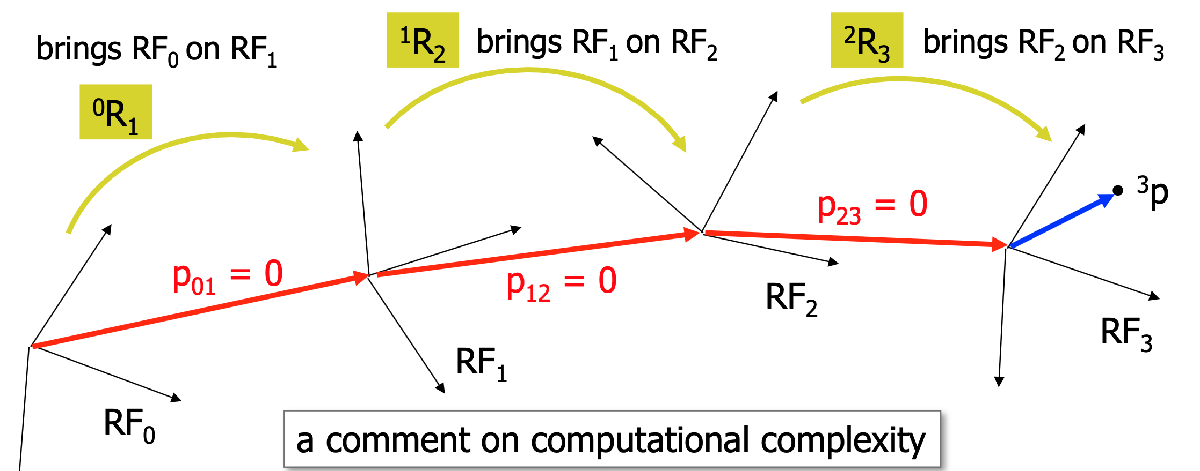

% each rotation may be made to respect to the current frame or to a fixed
% reference frame, in  the second case  composition of rotation matrix is
% not commutative.

syms R_BC R_CD q_d

R_BC=[1 0 0; 0 1 0; 0 0 1];
R_CD=[1 0 0; 0 1 0; 0 0 1];
q_d=[1 1 1].';

q_a=(R_AB*R_BC*R_CD)*q_d; % computationally more expensive

q_a=(R_AB*(R_BC*(R_CD*q_d))); % computationally less expensive


# MINIMAL REPRESENTATION

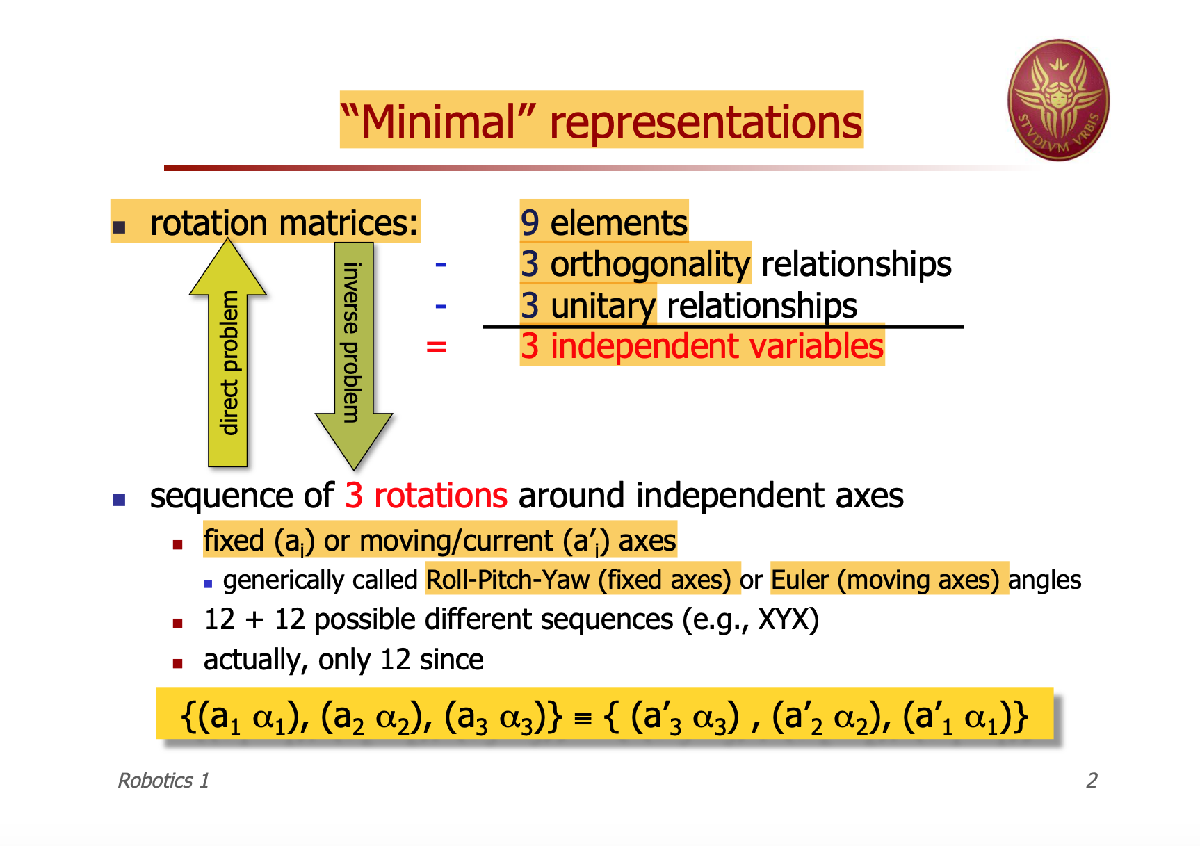

MINIMAL REPRESENTATION: $\phi ={\left\lbrack \varphi \;\;\vartheta \;\;\psi \;\right\rbrack }^T \;$ expresses the joint variable. A generic rotation matrix can be obtained by composing a suitable sequence of three elementary rotations while guaranteeing that two successive rotations are not made about parallel axes. i.e Euler ZXZ, ZYZ, .. or Roll-Pitch-Yaw, ..

A minimal representation of the special orthonormal group SO(m) requires m(m − 1)/2 parameters; thus, three parameters are needed to parameterize SO(3), whereas only one parameter is needed for a planar rotation SO(2). 

# EULER ANGLES ZX'Z" 

ZX'Z" (current frame)

## DIRECT PROBLEM

% ROTATIONS ARE APPLIED TO ROTATED AXIS (NOT FIXED)
syms phi theta psi r11 r12 r13 r21 r22 r23 r31 r32 r33
zeta=[phi theta psi].'

$$zeta = \left(\begin{array}{c} \varphi \\ \theta \\ \psi \end{array}\right)$$

R_zyz = @(zeta) R_z(zeta(1))*R_y(zeta(2))*R_z(zeta(3)); %very useful to solve inverse problem
% direct problem -> given phi, theta, psi, find R:
R_zxz = @(zeta) R_z(zeta(1))*R_x(zeta(2))*R_z(zeta(3)); %very useful to solve inverse problem
% given a vector v''' expressed in R_zxz(zeta) reference frame, find v
syms vx vy vz

v_R = [vx,vy,vz].';

R = R_zxz(zeta)

$$R = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\varphi \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)+\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

v = R * v_R

$$v = \left(\begin{array}{c} \mathrm{vx}\,\left(\cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right)\right)-\mathrm{vy}\,\left(\cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\right)+\mathrm{vz}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \mathrm{vx}\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)+\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right)\right)-\mathrm{vy}\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)-\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)\right)-\mathrm{vz}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \mathrm{vz}\,\cos\left(\theta \right)+\mathrm{vy}\,\cos\left(\psi \right)\,\sin\left(\theta \right)+\mathrm{vx}\,\sin\left(\psi \right)\,\sin\left(\theta \right) \end{array}\right)$$

## INVERSE PROBLEM

% inverse problem -> given R, find phi, theta, psi:

% zeta=[phi theta psi].'

zeta = deg2rad([45, 45, 45].');

R = R_zxz(zeta);

theta1 = rad2deg(atan2(+ sqrt(power(R(1,3),2)+power(R(2,3),2)),R(3,3)))

theta1 = 45


psi1 = rad2deg(atan2(R(3,1)/sin(theta1),R(3,2)/sin(theta1)))

psi1 = 45.0000


phi1 = rad2deg(atan2(R(1,3)/sin(theta1), -R(2,3)/sin(theta1)))

phi1 = 45.0000


theta2 = rad2deg(atan2(- sqrt(power(R(1,3),2)+power(R(2,3),2)),R(3,3)))

theta2 = -45


psi2 = rad2deg(atan2(R(3,1)/sin(theta2),R(3,2)/sin(theta2)))

psi2 = -135


phi2 = rad2deg(atan2(R(1,3)/sin(theta2), -R(2,3)/sin(theta2)))

phi2 = -135


% PROBLEM:
% ALWAYS PAIRS OF SOLUTIONS
% SINGULARITIES IN 0 AND +π and -π
% TRY zeta = deg2rad([45, 180, 45].');

# ROLL-PITCH-YAW ANGLES  

(Roll-Pitch-Yaw) XYZ (fixed frame) <-> (Euler) ZY'X" (current frame)

NOTE: be careful about FIXED FRAME, once the fixed frame is given, roll-pitch-yaw is computed as the reverse of the sequence (i.e. RPY fixed frame XYZ => ZYX Euler; RPY fixed frame ZYX => XYZ Euler)

i.e.				

 ZYX sequence of roll-pitch-yaw angles (α,β,γ), i.e., with respect to a set of fixed axes, is represented by the rotation matrix 

					
$$R_{\textrm{RPY}} \left(\alpha ,\beta ,\gamma \right)=R_x \left(\gamma \right)\;R_y \left(\beta \right)\;R_z \left(\alpha \right)$$


## DIRECT PROBLEM

% ROTATIONS ARE APPLIED TO FIXED AXIS, we need to revert
% always the previous transformation, in order to apply the
% new one

Roll = @(psi) R_x(psi); % ROLL is rotation around X FIXED

Pitch = @(theta) R_y(theta); % PITCH is rotation around Y FIXED

Yaw = @(phi) R_z(phi); % YAW is rotation around Z FIXED

R_RPY = Roll(psi) * ... % first ROLL
    (Roll(psi)' * Pitch(theta) * Roll(psi)) * ... % invert Roll, compute Pitch and Roll again
    (Roll(psi)' * Pitch(theta)' * Yaw(phi) * Roll(psi) * Pitch(theta)); % invert roll and pitch, compute yaw and pitch roll again

% which is equal to INVERTED ORDER! - current frame
R_RPY = @(zeta) Yaw(zeta(3)) * Pitch(zeta(2)) * Roll(zeta(1)); % inverted order

zeta=[phi theta psi].';

%zeta=[sym(pi/3) sym(pi/3) sym(-pi/2)].';

R_RPY(zeta)

$$ans = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

##  INVERSE PROBLEM

% inverse problem -> given R_RPY, find phi, theta, psi:

% zeta=[phi theta psi].'

zeta = deg2rad([45, 45, 45].');

R = R_RPY(zeta);

theta1 = rad2deg(atan2(- R(3,1), + sqrt(power(R(3,2),2)+power(R(3,3),2))))

theta1 = 45


psi1 = rad2deg(atan2(R(3,2)/cos(theta1),R(3,3)/cos(theta1)))

psi1 = 45.0000


phi1 = rad2deg(atan2(R(2,1)/cos(theta1), R(1,1)/cos(theta1)))

phi1 = 45.0000


theta2 = rad2deg(atan2(- R(3,1), - sqrt(power(R(3,2),2)+power(R(3,3),2))))

theta2 = 135


psi2 = rad2deg(atan2(R(3,2)/cos(theta2),R(3,3)/cos(theta2)))

psi2 = -135


phi2 = rad2deg(atan2(R(2,1)/cos(theta2), R(1,1)/cos(theta2)))

phi2 = -135


% PROBLEM:
% ALWAYS PAIRS OF SOLUTIONS FOR R(3,1)<0 W.R.T π/2
% SINGULARITIES IN +π/2 AND -π/2
% TRY zeta = deg2rad([45, 90, 45].');

# HOMOGENEOUS COORDINATES

## T-MATRIX					

Describes the relation between reference frames: translation + rotation.											

- it is always invertible ${\left({}^A_{\;}T^{\;}_B\right)}^{-1} =^B T_A$					

- can be composed, i.e., ${}^A_{\;}T^{\;}_C={}^A_{\;}T^{\;}_B{}^B_{\;}T^{\;}_C$ -> note: it does not commute! 

- notice that for the homogeneous transformation matrix the orthogonality property does not hold $T^{-1} =T^T$

- they are the **main tool for computing the direct kinematics of robot manipulators** 							

% Compact notation for applying Roto-Translation:
% 3D -> 4D
% a_P = a_P_b + a_R_b * b_P
% a_P_hom = a_T_b * b_P_hom

T = @(R, t) ...
    [R(1,1) R(1,2) R(1,3) t(1);
    R(2,1) R(2,2) R(2,3) t(2);
    R(3,1) R(3,2) R(3,3) t(3);
    0 0 0 1];

% T IS ALWAIS INVERTIBLE: (a_T_b)^-1 = b_T_a
syms tx ty tz
R = R_z(phi)

$$R = \left(\begin{array}{ccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


t = [tx ty tz].'

$$t = \left(\begin{array}{c} \mathrm{tx}\\ \mathrm{ty}\\ \mathrm{tz} \end{array}\right)$$


T_ = T(R,t)

$$T\_ = \left(\begin{array}{cccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0 & \mathrm{tx}\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0 & \mathrm{ty}\\ 0 & 0 & 1 & \mathrm{tz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% T CAN BE COMPOSED: a_T_b * b_T_c = a_T_c -> NOT COMMUTE

# AXIS/ANGLE

A nonminimal representation of orientation can be obtained by resorting to four parameters expressing a rotation of a given angle about an axis in space. This can be **advantageous in the problem of trajectory planning** for a manipulator’s end-effector orientation. 

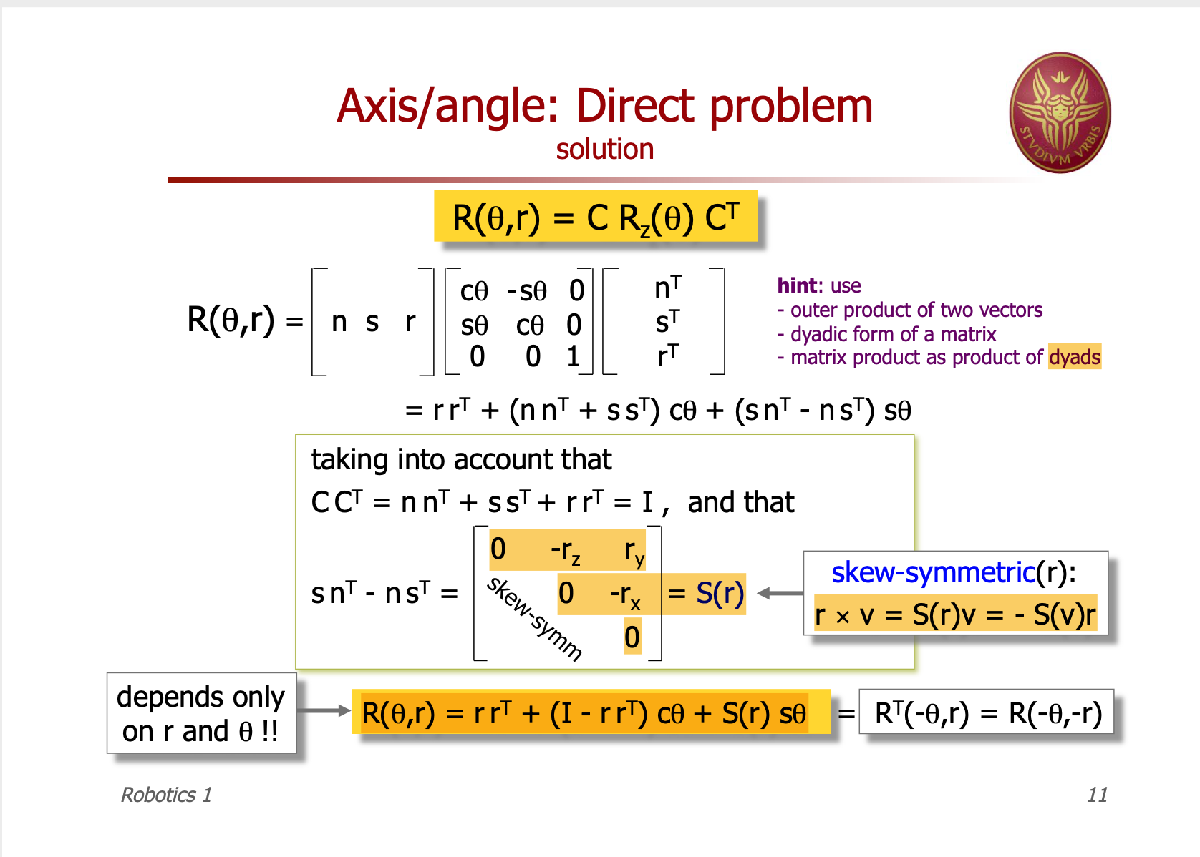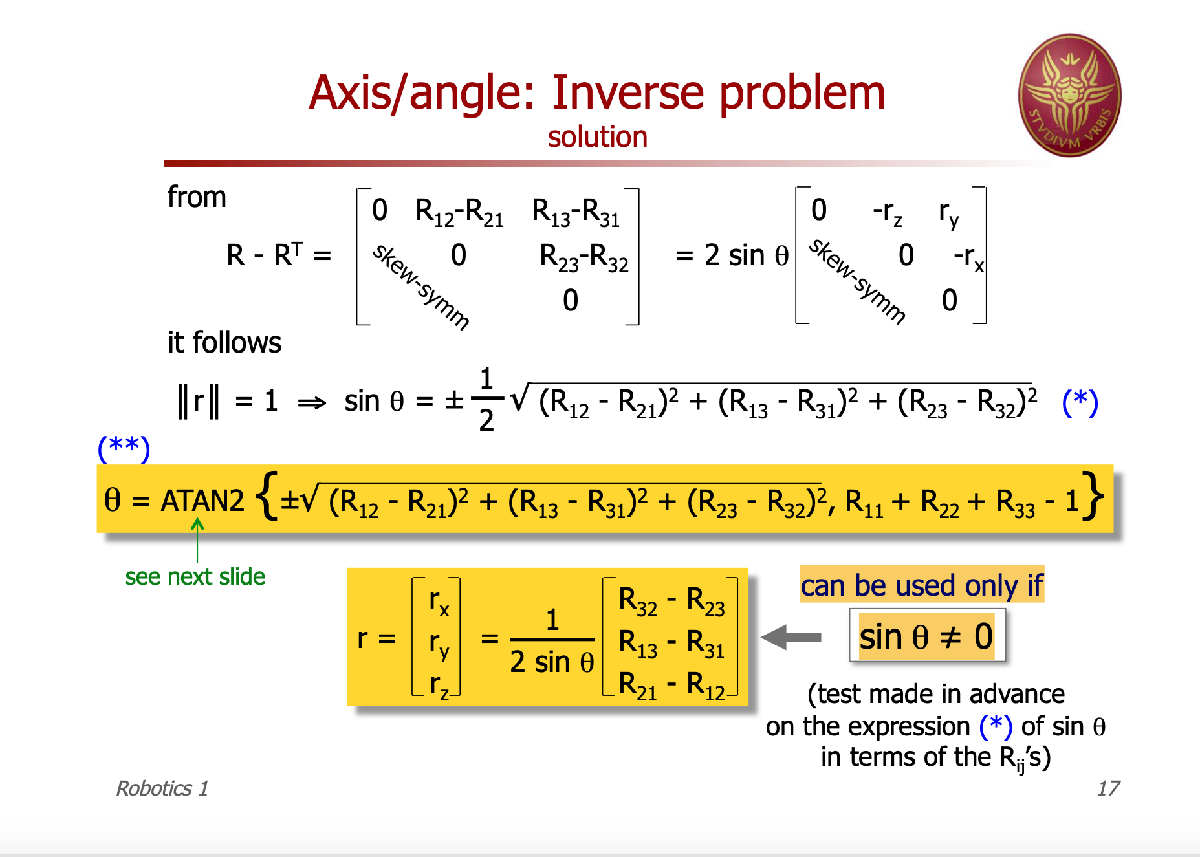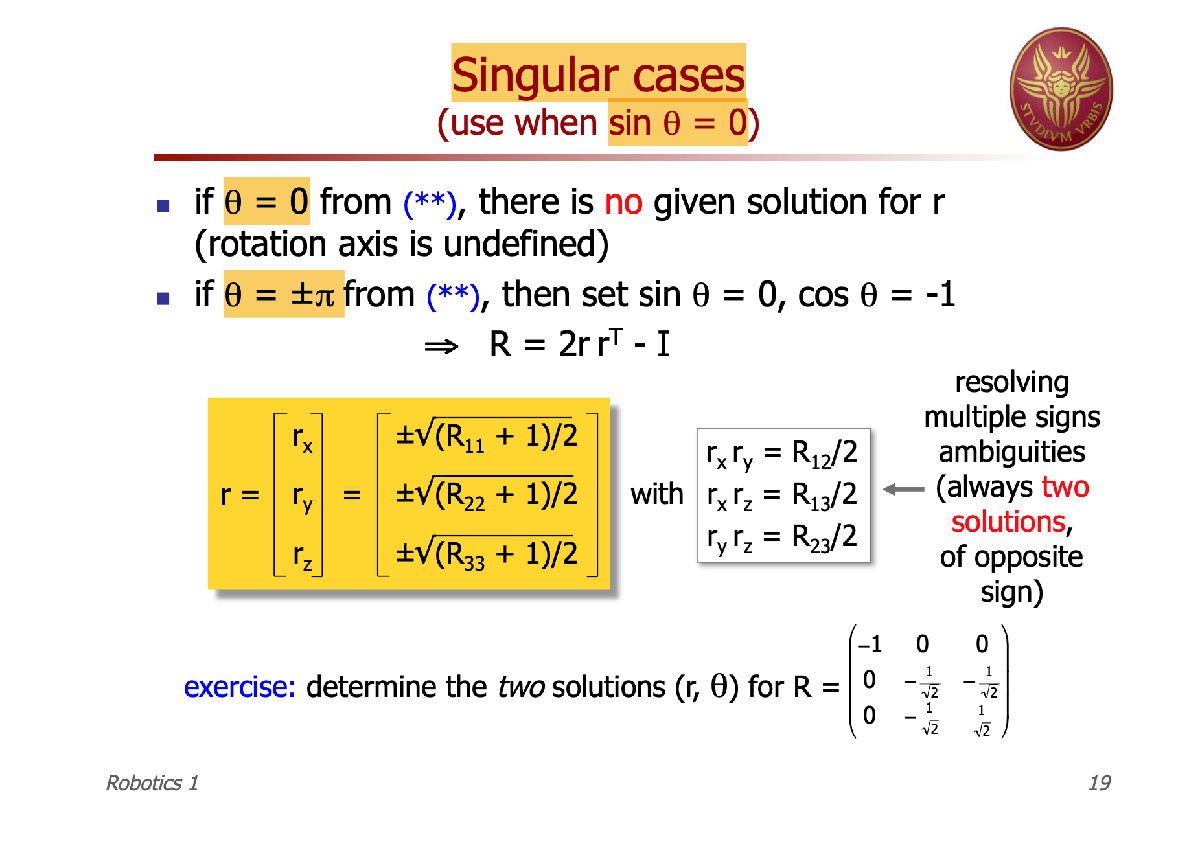

## DIRECT PROBLEM

x=[1,0,0].';
y=[0,1,0].';
z=[0,0,1].';

axis = z;

R = Rodriguez(deg2rad(45),axis)

R =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


R*axis % Rodriguez proof

ans =      0
     0
     1


## INVERSE PROBLEM (RODRIGUEZ FORMULA)

[0.6819,0.6866,0.2523,0,0.3572,-0.6136,0.7042,0,0.6383,-0.39,-0.6637,0,0.2588,0.267,0.1115,1]

ans =     0.6819    0.6866    0.2523         0    0.3572   -0.6136    0.7042         0    0.6383   -0.3900   -0.6637         0    0.2588    0.2670    0.1115    1.0000


[angle, axis] = Rodriguez_inv(R)

angle = 0.7854

axis =      0     0     1


[angle_, axis_] = quaternion(R)

angle = 0.7854

axis =          0
         0
    1.0000


angle_ = 0.7854

axis_ =          0
         0
    1.0000


function R = Rodriguez(theta, axis)
R = axis * axis.' + (eye(3) - axis * axis.') * cos(theta) + [0 -axis(3) axis(2) ; axis(3) 0 -axis(1) ; -axis(2) axis(1) 0 ]*sin(theta);
end

function [angle,axis]=Rodriguez_inv(R)
angle = atan2(sqrt((R(1,2)-R(2,1))^2+(R(1,3)-R(3,1))^2+(R(2,3)-R(3,2))^2),(R(1,1)+R(2,2)+R(3,3)-1));
if angle==0
    axis = 'undefined'
else if abs(angle)==pi
        axis = [sqrt((R(1,1)+1)/2),sqrt((R(2,2)+1)/2),sqrt((R(3,3)+1)/2)];
    else
        axis = 1/(2*sin(angle)).*[R(3,2)-R(2,3),R(1,3)-R(3,1),R(2,1)-R(1,2)];
    end
end
end

function [angle,axis]=quaternion(R)
eta = 0.5*sqrt(R(1,1)+R(2,2)+R(3,3)+1);
epsilon=0.5.*[sign(R(3,2)-R(2,3))*sqrt(R(1,1)-R(2,2)-R(3,3)+1);
    sign(R(1,3)-R(3,1))*sqrt(-R(1,1)+R(2,2)-R(3,3)+1);
    sign(R(2,1)-R(1,2))*sqrt(-R(1,1)-R(2,2)+R(3,3)+1)];
angle=2*acos(eta)
axis=epsilon./sin(angle/2)
end